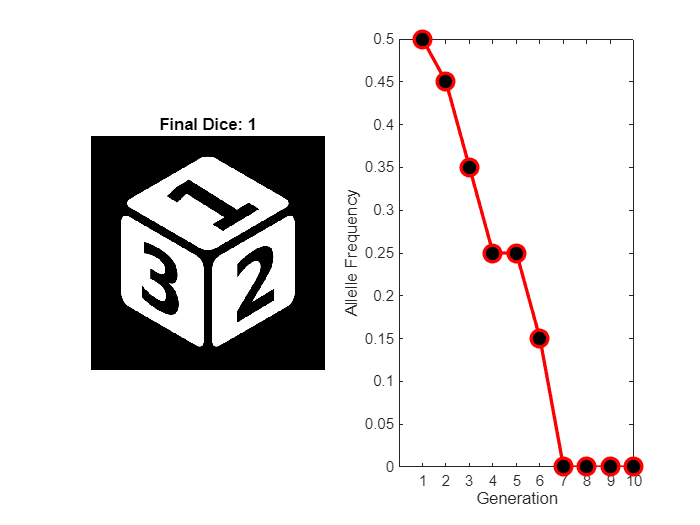

clear
population_size = 20; 
generations = 10;
allelefrequencies(1,1) = 0.5; % Uniform Prior Distribution for the allele frequency of the 1st generation
rng(44,"twister") %Varying Seed leads to extinction of organisms with desirable or undesirable trait
sz = [generations population_size];  % Size of table;
for i=1:population_size
    varNames(i) = "Allele" + " " +  num2str(i);
    varTypes(i) = "double";
end

allele_frequency_table = table('Size',sz,'VariableTypes', varTypes, 'VariableNames',varNames);

z = zeros(1,population_size/2);
o = ones(1,population_size/2);
h = [z o];
h = h(randperm(length(h)));
allele_frequency_table(1,:) = array2table(h,'VariableNames',varNames);

% Set up figure for animation
figure;
axis off;
hold on;

% Load dice images
dice_folder = 'C:\Users\lenovo\Downloads\DiceImages';  % Folder containing dice images
dice_images = cell(6, 1);
for i = 1:6
    dice_images{i} = imread([dice_folder '\' 'dice' num2str(i) '.png']);
end

% Animation loop for generations
for g = 2:generations
    % Dice roll animation (show a rolling dice effect)
    dice_val = randi([1 6], 1, 5); % Simulate rolling 5 dice
    for roll = 1:5
        dice_img = dice_images{dice_val(roll)};  % Get current dice image
        subplot(1, 2, 1); % Create a subplot for the dice
        imshow(dice_img); % Display dice image
        title('Rolling the Dice...');
        pause(0.3); % Pause to simulate the roll
    end
    
    % After rolling, choose final dice image and display it
    final_dice = randi([1 6], 1);  % Final roll
    subplot(1, 2, 1); % Dice subplot
    imshow(dice_images{final_dice});
    title(['Final Dice: ', num2str(final_dice)]);
    
    % Random sampling from a binomial distribution
    allele_no = binornd(population_size,allelefrequencies(g-1));   
    z = zeros(1,population_size-allele_no);
    o = ones(1,allele_no);
    h = [z o];
    h = h(randperm(length(h)));
    allele_frequency_table(g,:) = array2table(h,'VariableNames',varNames);
    allelefrequencies(1,g) = sum(table2array(allele_frequency_table(g,:))) / population_size;
    
    % Plot the current generation as colored squares
    subplot(1, 2, 2); % Create subplot for the allele squares
    axis off;
    hold on;
    for i = 1:population_size
        if h(i) == 1
            fill([i-1 i-1 i i], [g-1 g g g-1], 'r'); % Red square for allele 1
        else
            fill([i-1 i-1 i i], [g-1 g g g-1], 'b'); % Blue square for allele 0
        end
    end
    
    pause(0.5); % Pause to show the generation's alleles
end
hold off;

plot(allelefrequencies,'Color',"Red",'LineWidth',2,'Marker','o','MarkerFaceColor','black','MarkerEdgeColor',"auto",'MarkerSize',10)
xticks(1:10)
xtickangle(0)
xlabel("Generation")
ylabel("Allelle Frequency")